# **MATLAB TUTORIAL 6:**

# **ARRAY OPERATORS**

Please complete the following problems in this Livescript unless otherwise indicated. Remember to create a folder with the name Tutorial6_username (e.g. if your username is abc, then Tutorial6_abc) to put all the files and figures related to the Tutorial (including this Livescript). When you are finished, zip the folder and upload it to the BlackBoard Assignment submission box. 

### 6.1 Matrix Algebra

**Matrix multiplication and elementwise array multiplication**

Two arrays A and B representing matrices A and B are given as:

$A=\left\lbrack \begin{array}{ccc}
1 & 2 & 3\\
4 & 5 & 6\\
7 & 8 & 9
\end{array}\right\rbrack$    and  $B=\left\lbrack \begin{array}{ccc}
0\ldotp 4667 & -0\ldotp 3333 & 0\ldotp 1333\\
-0\ldotp 0333 & 0\ldotp 6667 & 0\ldotp 3667\\
-0\ldotp 3333 & -0\ldotp 3333 & 0\ldotp 3333
\end{array}\right\rbrack$

Multiply the matrices C = AB =

A = [ 1 , 2 , 3 ; 4 , 5 , 6 ; 7 , 8 , 9];
B = [ 0.4667 -0.3333 0.1333 ; -0.0333 , 0.6667 , 0.3667 ; -0.3333 -0.3333 0.3333]

B =     0.4667   -0.3333    0.1333
   -0.0333    0.6667    0.3667
   -0.3333   -0.3333    0.3333



C = A*B

C =    -0.5998    0.0002    1.8666
   -0.2995    0.0005    4.3665
    0.0008    0.0008    6.8664


How are the matrices A and B related?

Multiply the arrays A and B elementwise, using the .* operator: D = A.*B =

D=A.*B

D =     0.4667   -0.6666    0.3999
   -0.1332    3.3335    2.2002
   -2.3331   -2.6664    2.9997


Invert matrix D: $D^{-1}$ =

det(D)*transpose(D)

ans =     6.4463   -1.8398  -32.2258
   -9.2074   46.0437  -36.8295
    5.5236   30.3901   41.4331


**Singular Matrices**

A matrix G is given as:


$$G=\left\lbrack \begin{array}{ccc}
1 & 2 & 3\\
-\frac{1}{3} & -\frac{2}{3} & -1\\
7 & 8 & 9
\end{array}\right\rbrack$$


What happens if you try to invert matrix G?

G = [ 1 2 3 ; -1/3 -2/3 -1 ; 7 8 9]

G =     1.0000    2.0000    3.0000
   -0.3333   -0.6667   -1.0000
    7.0000    8.0000    9.0000



%det(G) == 0
%no invert of G 

Compute the determinant of matrix G

determinant = G([1])*det(G(2:3,2:3))-G([4])*det(G(2:3,1:2:3))+G([7])*det(G(2:3,1:2))

determinant = 0

### 6.2 Linear Equations

Use Matlab to solve the following system of equations:


$$3x_1+1x_2+6x_3=12 \\
5x_1+4x_2+2x_3=1 \\
1x_1+3x_2+8x_3=-3

$$


P=[3,1,6;5,4,2;1,3,8]

P =      3     1     6
     5     4     2
     1     3     8


S=[12;1;-3]

S =     12
     1
    -3


X = P^-1*S

X =     3.6604
   -4.8113
    0.9717


X1 = X(1)

X1 = 3.6604

X2 = X(2)

X2 = -4.8113

X3 = X(3)

X3 = 0.9717

### 6.3 Array Operations and Sub-arrays

**Plotting curves**

Create an array x of values from -10 to 10, spaced by 0.1 (use the colon operator). Use an array-operation to compute the array y y = sin(1/x). Plot array y versus array x.

x = [ -10 : 0.1 : 10]

x =   -10.0000   -9.9000   -9.8000   -9.7000   -9.6000   -9.5000   -9.4000   -9.3000   -9.2000   -9.1000   -9.0000   -8.9000   -8.8000   -8.7000   -8.6000   -8.5000   -8.4000   -8.3000   -8.2000   -8.1000   -8.0000   -7.9000   -7.8000   -7.7000   -7.6000   -7.5000   -7.4000   -7.3000   -7.2000   -7.1000   -7.0000   -6.9000   -6.8000   -6.7000   -6.6000   -6.5000   -6.4000   -6.3000   -6.2000   -6.1000   -6.0000   -5.9000   -5.8000   -5.7000   -5.6000   -5.5000   -5.4000   -5.3000   -5.2000   -5.1000


y = sin(1./x)

y =    -0.0998   -0.1008   -0.1019   -0.1029   -0.1040   -0.1051   -0.1062   -0.1073   -0.1085   -0.1097   -0.1109   -0.1121   -0.1134   -0.1147   -0.1160   -0.1174   -0.1188   -0.1202   -0.1216   -0.1231   -0.1247   -0.1262   -0.1279   -0.1295   -0.1312   -0.1329   -0.1347   -0.1366   -0.1384   -0.1404   -0.1424   -0.1444   -0.1465   -0.1487   -0.1509   -0.1532   -0.1556   -0.1581   -0.1606   -0.1632   -0.1659   -0.1687   -0.1716   -0.1745   -0.1776   -0.1808   -0.1841   -0.1876   -0.1911   -0.1948


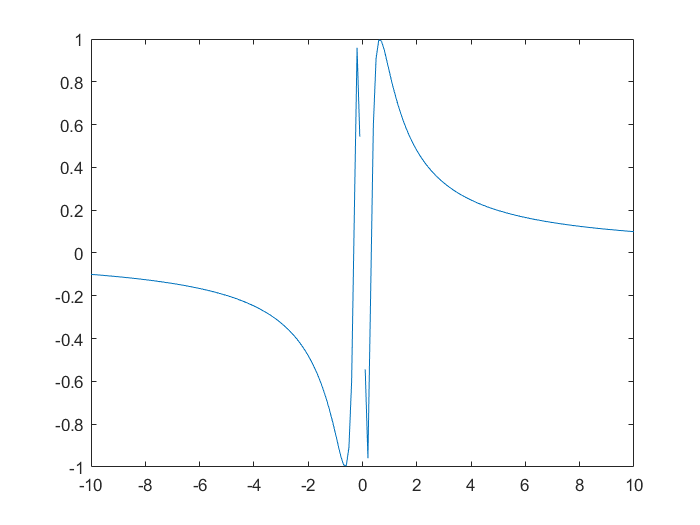


plot(x,y)

**Plotting vectors and streamlines**

Create a vector plot (using the function  **quiver() **) of the velocity ﬁeld  *u = y + sin(x)*,  *v = cos(x + y)* in the range 0 < x < 10 and 0 < y < 5. Plot the same velocity ﬁeld with streamlines using the function **streamslice()**

 Try this program ﬁrst using loops.

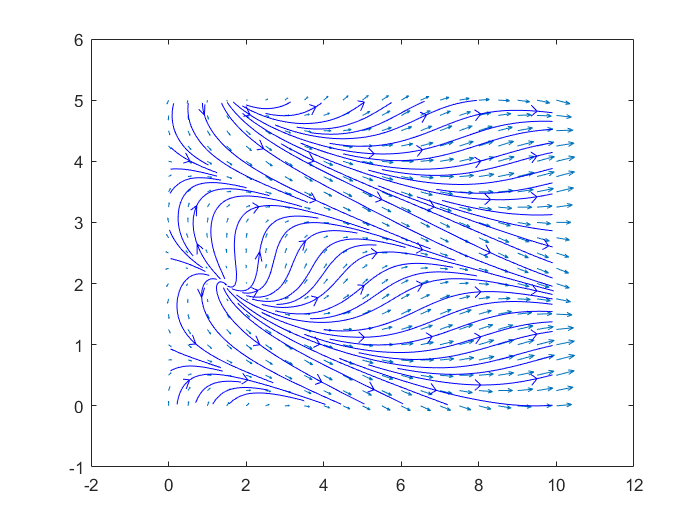

run arrayopreation.m

quiver(x,y,u,v)

streamslice(x,y,u,v)

Modify your program to only use array operations. The **meshgrid()** function may prove essential.

[u,v]=meshgrid(y+sin(x),cos(x+y))

u =          0    0.7294    1.3415    1.7475    1.9093    1.8485    1.6411    1.3992    1.2432    1.2725    1.5411    2.0445    2.7206    3.4651    4.1570    4.6880    4.9894    5.0485    4.9121    4.6748    4.4560
         0    0.7294    1.3415    1.7475    1.9093    1.8485    1.6411    1.3992    1.2432    1.2725    1.5411    2.0445    2.7206    3.4651    4.1570    4.6880    4.9894    5.0485    4.9121    4.6748    4.4560
         0    0.7294    1.3415    1.7475    1.9093    1.8485    1.6411    1.3992    1.2432    1.2725    1.5411    2.0445    2.7206    3.4651    4.1570    4.6880    4.9894    5.0485    4.9121    4.6748    4.4560
         0    0.7294    1.3415    1.7475    1.9093    1.8485    1.6411    1.3992    1.2432    1.2725    1.5411    2.0445    2.7206    3.4651    4.1570    4.6880    4.9894    5.0485    4.9121    4.6748    4.4560
         0    0.7294    1.3415    1.7475    1.9093    1.8485    1.6411    1.3992    1.2432    1.2725    1.5411    2.0445    2.7206    3.4651    4.1570  

v =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    0.7317    0.7317    0.7317    0.7317    0.7317    0.7317    0.7317    0.7317    0.7317    0.7317    0.7317    0.7317    0.7317    0.7317    0.7317    0.7317    0.7317    0.7317    0.7317    0.7317    0.7317
    0.0707    0.0707    0.0707    0.0707    0.0707    0.0707    0.0707    0.0707    0.0707    0.0707    0.0707    0.0707    0.0707    0.0707    0.0707    0.0707    0.0707    0.0707    0.0707    0.0707    0.0707
   -0.6282   -0.6282   -0.6282   -0.6282   -0.6282   -0.6282   -0.6282   -0.6282   -0.6282   -0.6282   -0.6282   -0.6282   -0.6282   -0.6282   -0.6282   -0.6282   -0.6282   -0.6282   -0.6282   -0.6282   -0.6282
   -0.9900   -0.9900   -0.9900   -0.9900   -0.9900   -0.9900   -0.9900   -0.9900   -0.9900   -0.9900   -0.9900   -0.9900   -0.9900   -0.9900   -0.9900  

surf(u,v)

What do the arrays produced by **meshgrid()** look like? Are they arranged in the order you would expect?

**Extracting sub-matrices**

A matrix M is given as: 


$$M=\left\lbrack \begin{array}{cccccc}
1 & 2 & 3 & 5 & 8\ldotp 5 & 2\\
-\frac{1}{3} & -\frac{2}{3} & -1 & 3 & 2 & -5\ldotp 1\\
7 & 8 & 9 & 2\ldotp 01 & -1 & 3
\end{array}\right\rbrack$$


 Copy the right half of matrix M (i.e. columns 4, 5 and 6) to matrix N.

M = [1 2 3 5 8.5 2 ; -1/3 -2/3 -1 3 2 -5.1 ; 7 8 9 2.01 -1 3]

M =     1.0000    2.0000    3.0000    5.0000    8.5000    2.0000
   -0.3333   -0.6667   -1.0000    3.0000    2.0000   -5.1000
    7.0000    8.0000    9.0000    2.0100   -1.0000    3.0000


N = M(1:3 , 4:6)

N =     5.0000    8.5000    2.0000
    3.0000    2.0000   -5.1000
    2.0100   -1.0000    3.0000


 Copy the odd numbered columns (1,3,5,...) of the 2nd row of matrix M to a matrix K.

K = M(2,[1,3,5])

K =    -0.3333   -1.0000    2.0000


**Area of a Circle**

We certainly know the value of π to very high precision. We now try a Monte-Carlo method, i.e. a method based on random numbers, to compute its value.

The area of a circle of radius r = 1 is π. To compute the area, we can create N random points, where every point N has a random x coordinate and a random y coordinate. We only consider random points where all the coordinates are in the range of [-1, 1], i.e. inside a square.

The ratio of the area of the circle to that of the square can therefore be approximated by the number of points inside the circle divided by the total number of points, as the number of points nears inﬁnity. Store the coordinates of the random points in a N×2 matrix. A point is located inside the circle if$x^2+y^2<1$ . To compute π, it is suﬃcient to multiply the area of the square (4) with the number Ni of points inside the circle divided by the overall number N of points. To improve the precision, you can simply increase the number of points.

Hint: A problem such as this where a particular operation is repeated for diﬀerent inputs lends itself very well to the use of a function.

Write the program.

roughpie(100)

    3.3200



ans = 3.3200

Your value for π(N = 1):

Your value for π(N = 10):

Your value for π(N = 100):

Your value for π(N = 1,000):

Your value for π(N = 10,000):

Your value for π(N = 100,000):

Your value for π(N = 1,000,000):

Once your script is working, try to eliminate all loops and if statements by using array operations. Keep in mind that relational operators (==, >, < etc.) can be used with arrays. For instance:

>> a=([1,2,6,3,2,7,10,9] > 3)

will return an array a equal to [0,0,1,0,0,1,1,1].

roughpie(1)

     4



ans = 4

roughpie(10)

    3.2000



ans = 3.2000

roughpie(100)

    3.2400



ans = 3.2400

roughpie(1000)

    3.0720



ans = 3.0720

roughpie(10000)

    3.1072



ans = 3.1072

roughpie(100000)

    3.1140



ans = 3.1140

roughpie(1000000)

    3.1099



ans = 3.1099

**Finding Primes and Plotting them**

Write a program that ﬁnds all the primes in the interval from lower bound to upper bound, and then plots their distribution.

The program should ﬁrst prompt the user for a range of integers, asking for a lower and upper bound. A for-loop will then iterate over each number, calling the function written previously to check whether the number is a prime. Then the function will mark integers that are primes with a value of 1, other integers with 0.

Finally, the script must plot the resulting array to visualise the distribution of the primes.

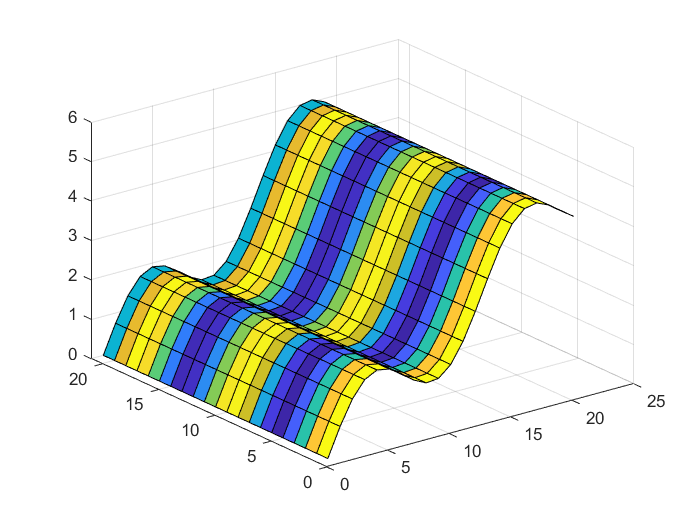

  Columns 1 through 7

     1     0     1     0     1     0     0

  Columns 8 through 14

     0     1     0     1     0     0     0

  Columns 15 through 21

     1     0     1     0     0     0     1

  Columns 22 through 28

     0     0     0     0     0     1     0

  Columns 29 through 35

     1     0     0     0     0     0     1

  Columns 36 through 42

     0     0     0     1     0     1     0

  Columns 43 through 49

     0     0     1     0     0     0     0

  Columns 50 through 56

     0     1     0     0     0     0     0

  Columns 57 through 63

     1     0     1     0     0     0     0

  Columns 64 through 70

     0     1     0     0     0     1     0

  Columns 71 through 77

     1     0     0     0     0     0     1

  Columns 78 through 84

     0     0     0     1     0     0     0

  Columns 85 through 91

     0     0     1     0     0     0     0

  Columns 92 through 98

     0     0     0     1     0     0     0



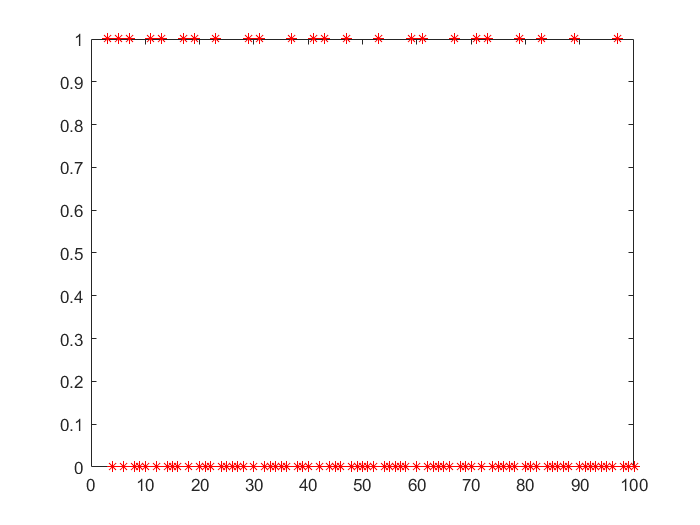

run checkp.m